%%Larios Torres Alioscha Nicolás 
%%Practica 08
clear;
clc;
close all;

Ra = 2;
Kt = 0.01;
b = 0.0012;
La = 0.023;
Ke = 0.01;
J = 0.001;

A = [-Ra/La   -Ke/La   0;
      Kt/J    -b/J     0;
      0        1       0];

B = [1/La;
     0;
     0];

C = eye(3);

D = zeros(3,1);

disp('Matriz A:')

Matriz A:


disp(A)

  -86.9565   -0.4348         0
   10.0000   -1.2000         0
         0    1.0000         0




disp('Matriz B:')

Matriz B:


disp(B)

   43.4783
         0
         0




disp('Matriz C:')

Matriz C:


disp(C)

     1     0     0
     0     1     0
     0     0     1




disp('Matriz D:')

Matriz D:


disp(D)

     0
     0
     0



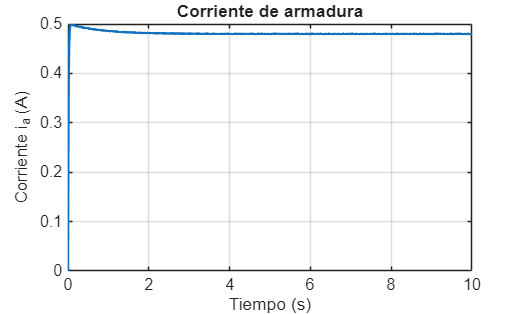


Va = 1;

x0 = [0;
      0;
      0];

tspan = [0 10];

f = @(t,x) A*x + B*Va;

[t,x] = ode45(f,tspan,x0);

ia = x(:,1);
omega = x(:,2);
theta = x(:,3);

figure
plot(t,ia,'LineWidth',1.5)
grid on
xlabel('Tiempo (s)')
ylabel('Corriente i_a (A)')
title('Corriente de armadura')

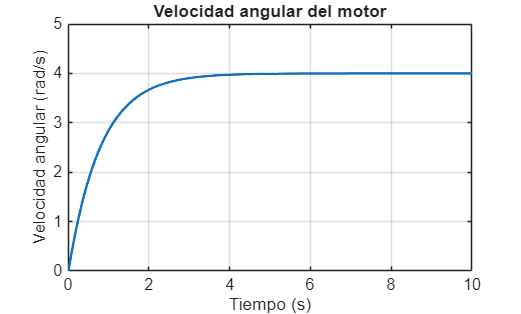


figure
plot(t,omega,'LineWidth',1.5)
grid on
xlabel('Tiempo (s)')
ylabel('Velocidad angular (rad/s)')
title('Velocidad angular del motor')

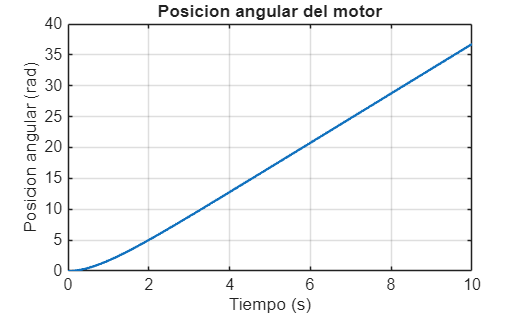


figure
plot(t,theta,'LineWidth',1.5)
grid on
xlabel('Tiempo (s)')
ylabel('Posicion angular (rad)')
title('Posicion angular del motor')